test dataset (batch1,2) 에서 값을 정규화하기

%idx = idxAll; %RMSE = 1032  - 잘 동작
idx = idx12 ; % training set - 잘 동작하지 않음
%idx = idx13 ; % training set - 잘 동작하지 않음
%idx = idx1;
key = [battery_dataset_new(idx).key]';
s = string([battery_dataset_new(idx).policy])

s = "4_4C-80PER_4_4C4_8C-80PER_4_8C4_8C-80PER_4_8C5_4C-40PER_3_6C5_4C-50PER_3C5_4C-60PER_3C5_4C-60PER_3C5_4C-60PER_3_6C5_4C-60PER_3_6C5_4C-70PER_3C5_4C-70PER_3C5_4C-80PER_5_4C5_4C-80PER_5_4C6C-30PER_3_6C6C-40PER_3C6C-40PER_3C6C-40PER_3_6C6C-40PER_3_6C6C-50PER_3C6C-50PER_3C6C-50PER_3_6C6C-50PER_3_6C6C-60PER_3C6C-60PER_3C7C-30PER_3_6C7C-30PER_3_6C7C-40PER_3C7C-40PER_3C7C-40PER_3_6C7C-40PER_3_6C8C-15PER_3_6C8C-15PER_3_6C8C-25PER_3_6C8C-25PER_3_6C8C-35PER_3_6C8C-35PER_3_6C1C_4PER_6C2C_10PER_6C2C_2PER_5C2C_7PER_5_5C3_6C_22PER_5_5C3_6C_2PER_4_85C3_6C_30PER_6C3_6C_9PER_5C4C_13PER_5C4C_31PER_54C_40PER_6C4C_4PER_4_85C4_4C_24PER_5C4_4C_47PER_5_5C4_4C_55PER_6C4_4C_8PER_4_85C4_65C_19PER_4_85C4_65C_44PER_5C4_65C_69PER_6C4_8C_80PER_4_8C4_8C_80PER_4_8C4_8C_80PER_4_8C4_9C_27PER_4_75C4_9C_61PER_4_5C4_9C_69PER_4_25C5_2C_10PER_4_75C5_2C_37PER_4_5C5_2C_50PER_4_25C5_2C_58PER_4C5_2C_66PER_3_5C5_2C_71PER_3C5_6C_25PER_4_5C5_6C_38PER_4_25C5_6C_47PER_4C5_6C_58PER_3_5C5_6C_5PER_4_75C5_6C_65PER_3C6C_20PER_4_5C6C_

s1 = string([{battery_dataset_new(idx).policy}])

s1 = 1×79 string array
    "4_4C-80PER_4_4C"    "4_8C-80PER_4_8C"    "4_8C-80PER_4_8C"    "5_4C-40PER_3_6C"    "5_4C-50PER_3C"    "5_4C-60PER_3C"    "5_4C-60PER_3C"    "5_4C-60PER_3_6C"    "5_4C-60PER_3_6C"    "5_4C-70PER_3C"    "5_4C-70PER_3C"    "5_4C-80PER_5_4C"    "5_4C-80PER_5_4C"    "6C-30PER_3_6C"    "6C-40PER_3C"    "6C-40PER_3C"    "6C-40PER_3_6C"    "6C-40PER_3_6C"    "6C-50PER_3C"    "6C-50PER_3C"    "6C-50PER_3_6C"    "6C-50PER_3_6C"    "6C-60PER_3C"    "6C-60PER_3C"    "7C-30PER_3_6C"    "7C-30PER_3_6C"    "7C-40PER_3C"    "7C-40PER_3C"    "7C-40PER_3_6C"    "7C-40PER_3_6C"    "8C-15PER_3_6C"    "8C-15PER_3_6C"    "8C-25PER_3_6C"    "8C-25PER_3_6C"    "8C-35PER_3_6C"    "8C-35PER_3_6C"    "1C_4PER_6C"    "2C_10PER_6C"    "2C_2PER_5C"    "2C_7PER_5_5C"    "3_6C_22PER_5_5C"    "3_6C_2PER_4_85C"    "3_6C_30PER_6C"    "3_6C_9PER_5C"    "4C_13PER_5C"    "4C_31PER_5"    "4C_40PER_6C"    "4C_4PER_4_85C"    "4_4C_24PER_5C"    "4_4C_47PER_5_5C"    "4_4C_55PER_6C"    "4_4C_8PER_4_85

policy = [{battery_dataset_new(idx).policy}]';
policy_str = string([{battery_dataset_new(idx).policy}]');
policy_readable = [{battery_dataset_new(idx).policy_readable}]';
policy_readable_str = string([{battery_dataset_new(idx).policy_readable}]');
Ic1 = [{battery_dataset_new(idx).Ic}]';
Ic2 = [battery_dataset_new(idx).Ic];
Ic3 = reshape(Ic2,input_size,length(policy));
Ic = Ic3';
cycle = [battery_dataset_new(idx).cycle_life ]';
x=Ic;
y=cycle;
[ynorm,ymin,yrate,xnorm,xmin,xrate] = minmax_norm_new(y,x);

min(y)

ans = 109

max(y)

ans = 711


yrate =  max(y) - min(y)

yrate = 602

ymin = min(y)

ymin = 109

ynorm = (y - ymin) / yrate

ynorm =     0.5299
    0.1993
    0.2392
    0.3804
    0.5100
    0.3688
    0.2807
    0.2093
    0.2907
    0.5864


yback = ynorm * yrate + ymin

yback =    428
   229
   253
   338
   416
   331
   278
   235
   284
   462


y

y =    428
   229
   253
   338
   416
   331
   278
   235
   284
   462


x

x =          0    4.3999    4.3999    4.4000    4.4000    4.4001    4.3999    4.3999    4.4001    4.4000    4.3999    4.4000    4.4001    4.4001    4.3999    4.3999    4.3998    4.4000    4.3997    4.3998    4.3999    4.3997    4.3999    4.4005    4.3997    4.3994    4.4001    4.3999    4.3996    4.4007    4.4000    4.3997    4.4001    4.4002    4.3998    4.4003    4.4001    4.3999    4.4002    4.4002    4.4000    4.3999    4.3998    4.3999    4.3999    4.4000    4.3999    4.3999    4.4001    4.4001
         0    4.8000    4.7997    4.8001    4.8000    4.8002    4.8001    4.8003    4.8002    4.8001    4.8000    4.8000    4.8002    4.7994    4.7998    4.8000    4.7996    4.8001    4.8001    4.8000    4.8001    4.8000    4.8001    4.7998    4.7997    4.7997    4.7998    4.7997    4.8000    4.7998    4.7999    4.8002    4.7999    4.8000    4.8001    4.8000    4.8000    4.8000    4.8000    4.8001    4.8002    4.7999    4.8000    4.7999    4.8001    4.8001    4.8000    4.7998    4.7999    4

min(min(x))

ans = 0

max(max(x))

ans = 8.0067

xrate =  max(max(x)) - min(min(x))

xrate = 8.0067

xmin = min(min(x))

xmin = 0

xnorm = (x - xmin) / xrate

xnorm =          0    0.5495    0.5495    0.5495    0.5495    0.5495    0.5495    0.5495    0.5496    0.5495    0.5495    0.5495    0.5496    0.5495    0.5495    0.5495    0.5495    0.5495    0.5495    0.5495    0.5495    0.5495    0.5495    0.5496    0.5495    0.5495    0.5495    0.5495    0.5495    0.5496    0.5495    0.5495    0.5496    0.5496    0.5495    0.5496    0.5495    0.5495    0.5496    0.5496    0.5495    0.5495    0.5495    0.5495    0.5495    0.5495    0.5495    0.5495    0.5495    0.5495
         0    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5994    0.5995    0.5995    0.5994    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995 

xback = xnorm * xrate + xmin

xback =          0    4.3999    4.3999    4.4000    4.4000    4.4001    4.3999    4.3999    4.4001    4.4000    4.3999    4.4000    4.4001    4.4001    4.3999    4.3999    4.3998    4.4000    4.3997    4.3998    4.3999    4.3997    4.3999    4.4005    4.3997    4.3994    4.4001    4.3999    4.3996    4.4007    4.4000    4.3997    4.4001    4.4002    4.3998    4.4003    4.4001    4.3999    4.4002    4.4002    4.4000    4.3999    4.3998    4.3999    4.3999    4.4000    4.3999    4.3999    4.4001    4.4001
         0    4.8000    4.7997    4.8001    4.8000    4.8002    4.8001    4.8003    4.8002    4.8001    4.8000    4.8000    4.8002    4.7994    4.7998    4.8000    4.7996    4.8001    4.8001    4.8000    4.8001    4.8000    4.8001    4.7998    4.7997    4.7997    4.7998    4.7997    4.8000    4.7998    4.7999    4.8002    4.7999    4.8000    4.8001    4.8000    4.8000    4.8000    4.8000    4.8001    4.8002    4.7999    4.8000    4.7999    4.8001    4.8001    4.8000    4.7998    4.7999 

x

x =          0    4.3999    4.3999    4.4000    4.4000    4.4001    4.3999    4.3999    4.4001    4.4000    4.3999    4.4000    4.4001    4.4001    4.3999    4.3999    4.3998    4.4000    4.3997    4.3998    4.3999    4.3997    4.3999    4.4005    4.3997    4.3994    4.4001    4.3999    4.3996    4.4007    4.4000    4.3997    4.4001    4.4002    4.3998    4.4003    4.4001    4.3999    4.4002    4.4002    4.4000    4.3999    4.3998    4.3999    4.3999    4.4000    4.3999    4.3999    4.4001    4.4001
         0    4.8000    4.7997    4.8001    4.8000    4.8002    4.8001    4.8003    4.8002    4.8001    4.8000    4.8000    4.8002    4.7994    4.7998    4.8000    4.7996    4.8001    4.8001    4.8000    4.8001    4.8000    4.8001    4.7998    4.7997    4.7997    4.7998    4.7997    4.8000    4.7998    4.7999    4.8002    4.7999    4.8000    4.8001    4.8000    4.8000    4.8000    4.8000    4.8001    4.8002    4.7999    4.8000    4.7999    4.8001    4.8001    4.8000    4.7998    4.7999    4


%cycle = cycle -1;
%cycle_data = [cycle key policy policy_readable];
cycle_data = [cycle key policy_str policy_readable_str];
cycleTable1 = array2table(cycle_data,...
    'VariableNames',{'cycle','key','policy','policy_readable'})

cycleTable1 = 79×4 table
    cycle      key           policy          policy_readable 
    _____    _______    _________________    ________________

    "428"    "b1c6"     "4_4C-80PER_4_4C"    "4.4C(80%)-4.4C"
    "229"    "b1c7"     "4_8C-80PER_4_8C"    "4.8C(80%)-4.8C"
    "253"    "b1c8"     "4_8C-80PER_4_8C"    "4.8C(80%)-4.8C"
    "338"    "b1c10"    "5_4C-40PER_3_6C"    "5.4C(40%)-3.6C"
    "416"    "b1c12"    "5_4C-50PER_3C"      "5.4C(50%)-3C"  
    "331"    "b1c15"    "5_4C-60PER_3C"      "5.4C(60%)-3C"  
    "278"    "b1c16"    "5_4C-60PER_3C"      "5.4C(60%)-3C"  
    "235"    "b1c17"    "5_4C-60PER_3_6C"    "5.4C(60%)-3.6C"
    "284"    "b1c18"    "5_4C-60PER_3_6C"    "5.4C(60%)-3.6C"
    "462"    "b1c19"    "5_4C-70PER_3C"      "5.4C(70%)-3C"  
    "269"    "b1c20"    "5_4C-70PER_3C"      "5.4C(70%)-3C"  
    "379"    "b1c21"    "5_4C-80

cycleTable = table(cycle, key, policy_str, policy_readable_str,Ic)

cycleTable = 79×5 table
    cycle      key         policy_str        policy_readable_str          Ic      
    _____    _______    _________________    ___________________    ______________

     428     "b1c6"     "4_4C-80PER_4_4C"     "4.4C(80%)-4.4C"      [1×100 double]
     229     "b1c7"     "4_8C-80PER_4_8C"     "4.8C(80%)-4.8C"      [1×100 double]
     253     "b1c8"     "4_8C-80PER_4_8C"     "4.8C(80%)-4.8C"      [1×100 double]
     338     "b1c10"    "5_4C-40PER_3_6C"     "5.4C(40%)-3.6C"      [1×100 double]
     416     "b1c12"    "5_4C-50PER_3C"       "5.4C(50%)-3C"        [1×100 double]
     331     "b1c15"    "5_4C-60PER_3C"       "5.4C(60%)-3C"        [1×100 double]
     278     "b1c16"    "5_4C-60PER_3C"       "5.4C(60%)-3C"        [1×100 double]
     235     "b1c17"    "5_4C-60PER_3_6C"     "5.4C(60%)-3

cycleTableSort = sortrows(cycleTable,1,'descend')

cycleTableSort = 79×5 table
    cycle      key         policy_str        policy_readable_str          Ic      
    _____    _______    _________________    ___________________    ______________

     711     "b2c48"    "6C_60PER_3C"         "6C(60%)-3C"          [1×100 double]
     462     "b1c19"    "5_4C-70PER_3C"       "5.4C(70%)-3C"        [1×100 double]
     440     "b2c20"    "4_4C_55PER_6C"       "4.4C(55%)-6C"        [1×100 double]
     428     "b1c6"     "4_4C-80PER_4_4C"     "4.4C(80%)-4.4C"      [1×100 double]
     416     "b1c12"    "5_4C-50PER_3C"       "5.4C(50%)-3C"        [1×100 double]
     405     "b1c25"    "6C-40PER_3C"         "6C(40%)-3C"          [1×100 double]
     398     "b2c7"     "3_6C_30PER_6C"       "3.6C(30%)-6C"        [1×100 double]
     390     "b1c42"    "8C-15PER_3_6C"       "8C(15%)

데이타 읽어 들이기.

전류 패턴에 따른 라이프 사이클 예측 ..

선형회귀 - 정규화 필요 없음.

x = 충전전류 - training set ( batch 1,2)

y = cycle count


%%%%%%%%%%%%%
% FNN/CNN/LSTM
mdl = fitlm(x,y)

mdl = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12 + x13 + x14 + x15 + x16 + x17 + x18 + x19 + x20 + x21 + x22 + x23 + x24 + x25 + x26 + x27 + x28 + x29 + x30 + x31 + x32 + x33 + x34 + x35 + x36 + x37 + x38 + x39 + x40 + x41 + x42 + x43 + x44 + x45 + x46 + x47 + x48 + x49 + x50 + x51 + x52 + x53 + x54 + x55 + x56 + x57 + x58 + x59 + x60 + x61 + x62 + x63 + x64 + x65 + x66 + x67 + x68 + x69 + x70 + x71 + x72 + x73 + x74 + x75 + x76 + x77 + x78 + x79 + x80 + x81 + x82 + x83 + x84 + x85 + x86 + x87 + x88 + x89 + x90 + x91 + x92 + x93 + x94 + x95 + x96 + x97 + x98 + x99 + x100

Estimated Coefficients:
                    Estimate      SE    tStat    pValue
                   ___________    __    _____    ______

    (Intercept)              0    0      NaN      NaN  
    x1      

coeff = mdl.Coefficients.Estimate

coeff = 	1.0e+05 *

         0
         0
    0.0014
   -0.0013
    0.0042
   -0.0044
   -0.1182
   -0.0416
    0.2466
   -0.0674


x(1,:)

ans =          0    4.3999    4.3999    4.4000    4.4000    4.4001    4.3999    4.3999    4.4001    4.4000    4.3999    4.4000    4.4001    4.4001    4.3999    4.3999    4.3998    4.4000    4.3997    4.3998    4.3999    4.3997    4.3999    4.4005    4.3997    4.3994    4.4001    4.3999    4.3996    4.4007    4.4000    4.3997    4.4001    4.4002    4.3998    4.4003    4.4001    4.3999    4.4002    4.4002    4.4000    4.3999    4.3998    4.3999    4.3999    4.4000    4.3999    4.3999    4.4001    4.4001


training set 에서는 정말 잘 동작함.

RMSE 가 정말 작다.

yhat = x*coeff(2:101)+coeff(1)

yhat =   428.0000
  229.0000
  253.0000
  338.0000
  416.0000
  331.0000
  278.0000
  235.0000
  284.0000
  462.0000


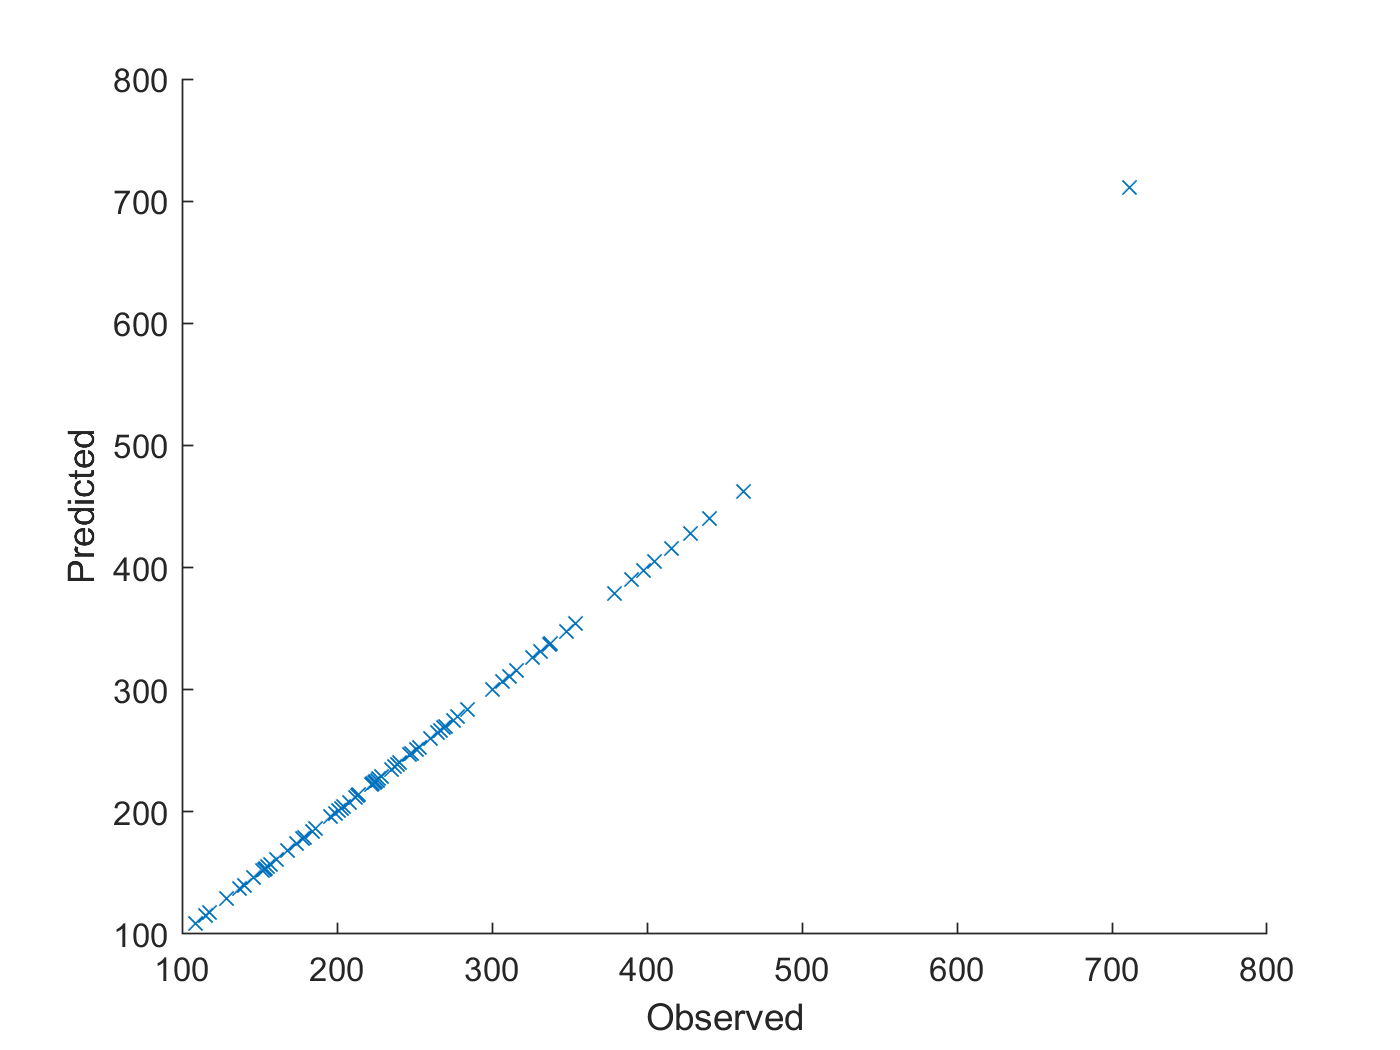

figure
hold on
plot(y,yhat,'x')
xlabel("Observed")
ylabel("Predicted")
hold off

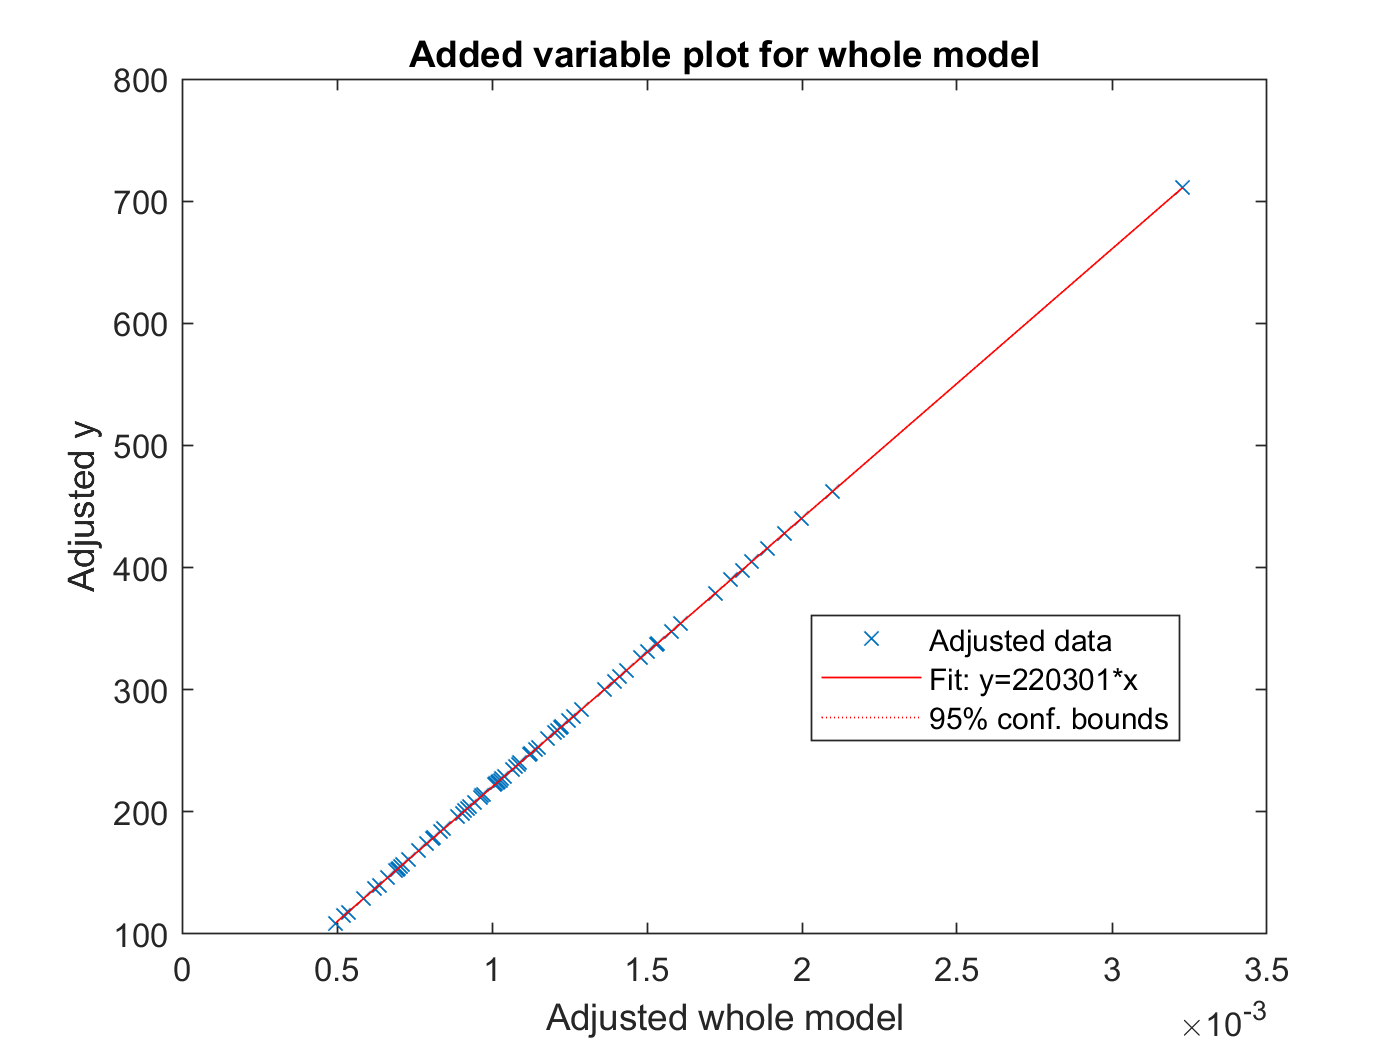


%capHat = Ic(1)

plot(mdl)

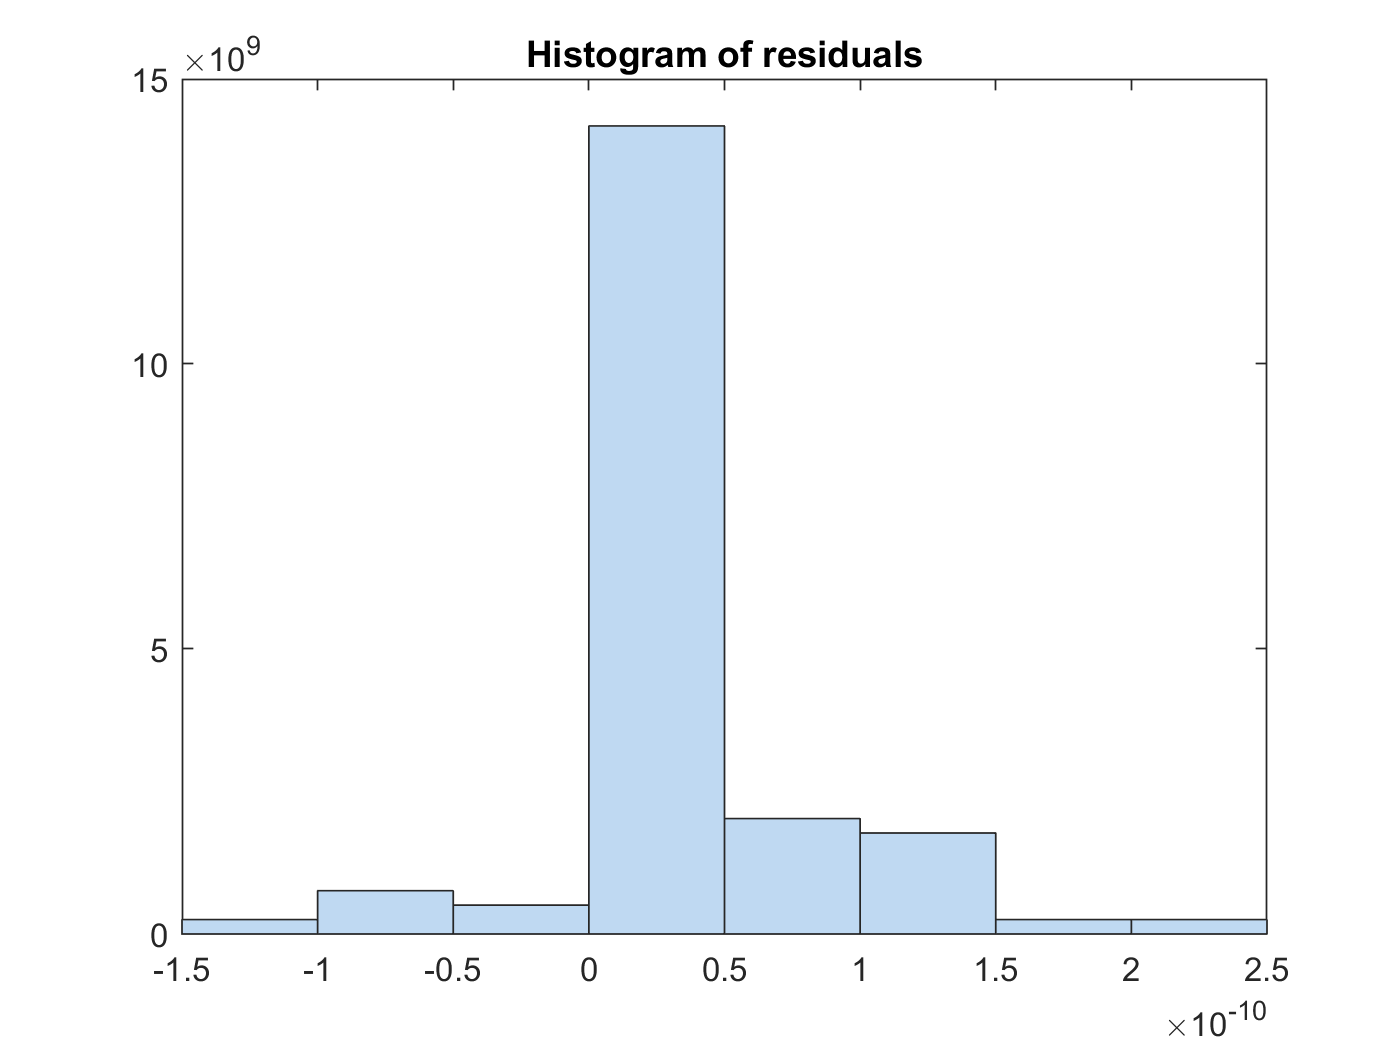

plotResiduals(mdl)




% yfit = predict(mdl,Ic)
yfit = predict(mdl,Ic)

yfit =   428.0000
  229.0000
  253.0000
  338.0000
  416.0000
  331.0000
  278.0000
  235.0000
  284.0000
  462.0000




y= cycle;
MAE = mean(abs(yfit-y))

MAE = 7.0733e-11

adjMAE = MAE/range(y)

adjMAE = 1.1750e-13

range(y) % y = range(X)는 X에 포함된 표본 데이터의 최댓값과 최솟값 간의 차이를 반환합니다.

ans = 602


(y - yhat)    % Errors

ans = 	1.0e+-9 *

   -0.5682
   -0.0883
   -0.0234
    0.1353
    0.0700
   -0.0985
    0.0377
   -0.0035
    0.2129
    0.0904


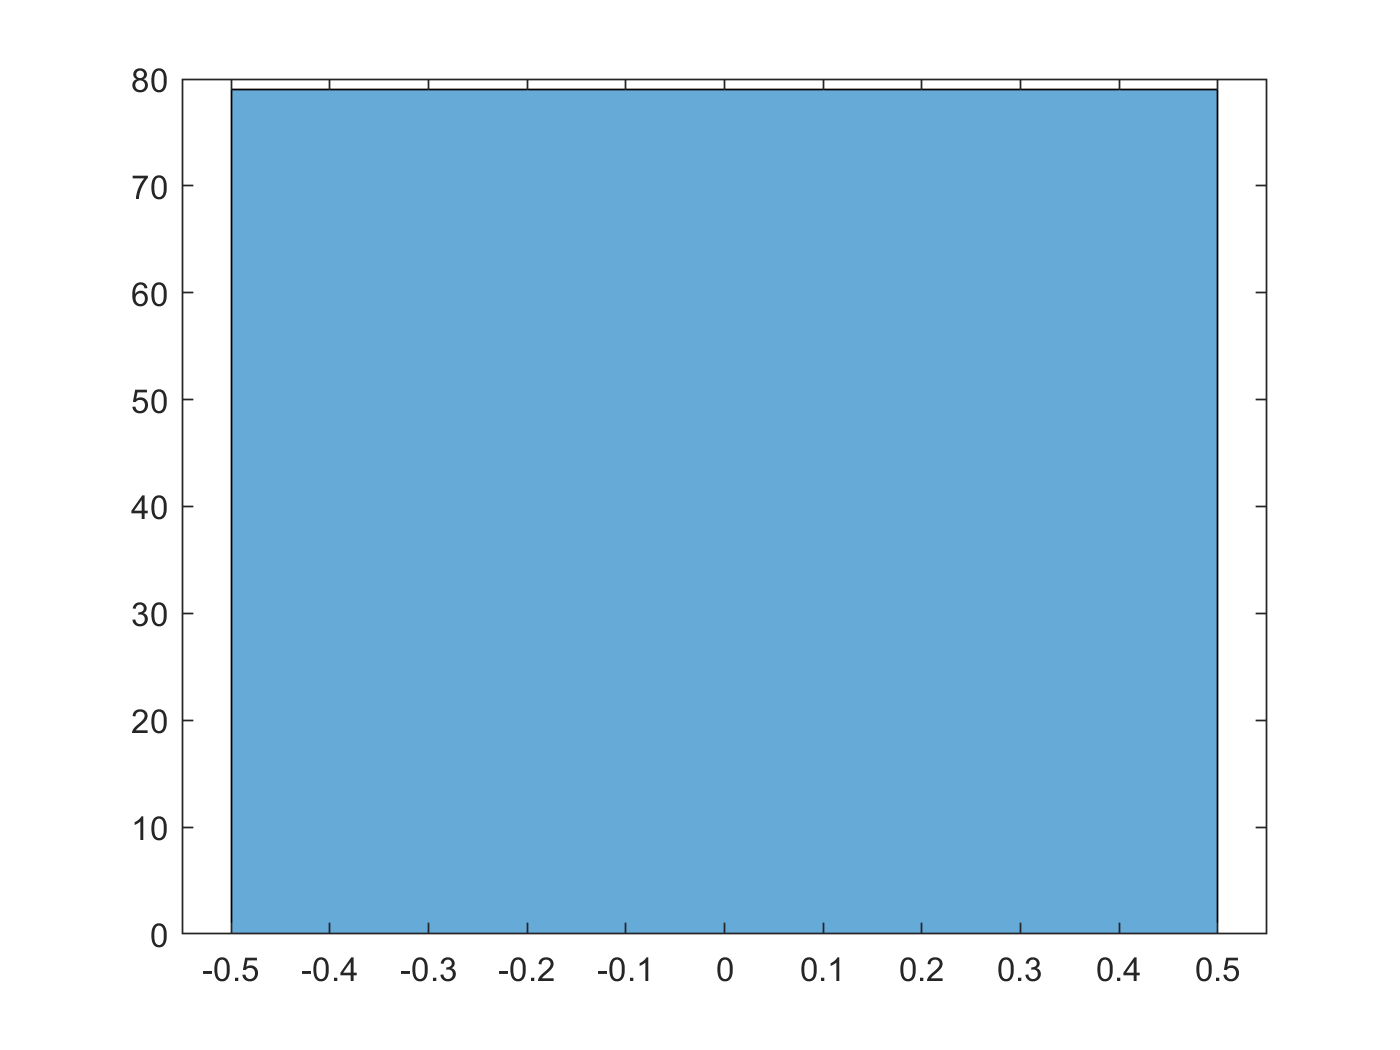

(y - yhat).^2;   % Squared Error
histogram((y - yhat).^2)

mean((y - yhat).^2);   % Mean Squared Error
RMSE = sqrt(mean((y - yhat).^2))  % Root Mean Squared Error

RMSE = 1.0158e-10

% 이것으로 입력신호(사용자 패턴)에 대해 예상되는 사이클을 예상할 수 있다.


%{
outlier1 = mdl.Residuals.Raw > 50 ;
outlier2 = mdl.Residuals.Raw < -50 ;
outlier =  outlier1 + outlier2 ;
find(outlier);
mdl = fitlm(x,y,'Exclude',find(outlier))
coeff = mdl.Coefficients.Estimate
x(1,:);
yhat = x*coeff(2:101)+coeff(1)
figure
hold on
plot(y,yhat,'x')
xlabel("Observed")
ylabel("Predicted")
hold off

%capHat = Ic(1)

plot(mdl)
plotResiduals(mdl)



% yfit = predict(mdl,Ic)
yfit = predict(mdl,Ic)


y= cycle;
MAE = mean(abs(yfit-y))
adjMAE = MAE/range(y)
range(y) % y = range(X)는 X에 포함된 표본 데이터의 최댓값과 최솟값 간의 차이를 반환합니다.

(y - yhat)    % Errors
(y - yhat).^2;   % Squared Error
histogram((y - yhat).^2)
mean((y - yhat).^2);   % Mean Squared Error
RMSE = sqrt(mean((y - yhat).^2))  % Root Mean Squared Error
% 이것으로 입력신호(사용자 패턴)에 대해 예상되는 사이클을 예상할 수 있다.
%}


training set (b1,2)로 b1 예측 - 정확함.

% predict batch1 from model from model
idx = idx1;
Ic_ = [battery_dataset_new(idx).Ic];
x = (reshape(Ic_,input_size,[]))';
y = [battery_dataset_new(idx).cycle_life ]';

yhat = predict(mdl,x)

yhat =   428.0000
  229.0000
  253.0000
  338.0000
  416.0000
  331.0000
  278.0000
  235.0000
  284.0000
  462.0000


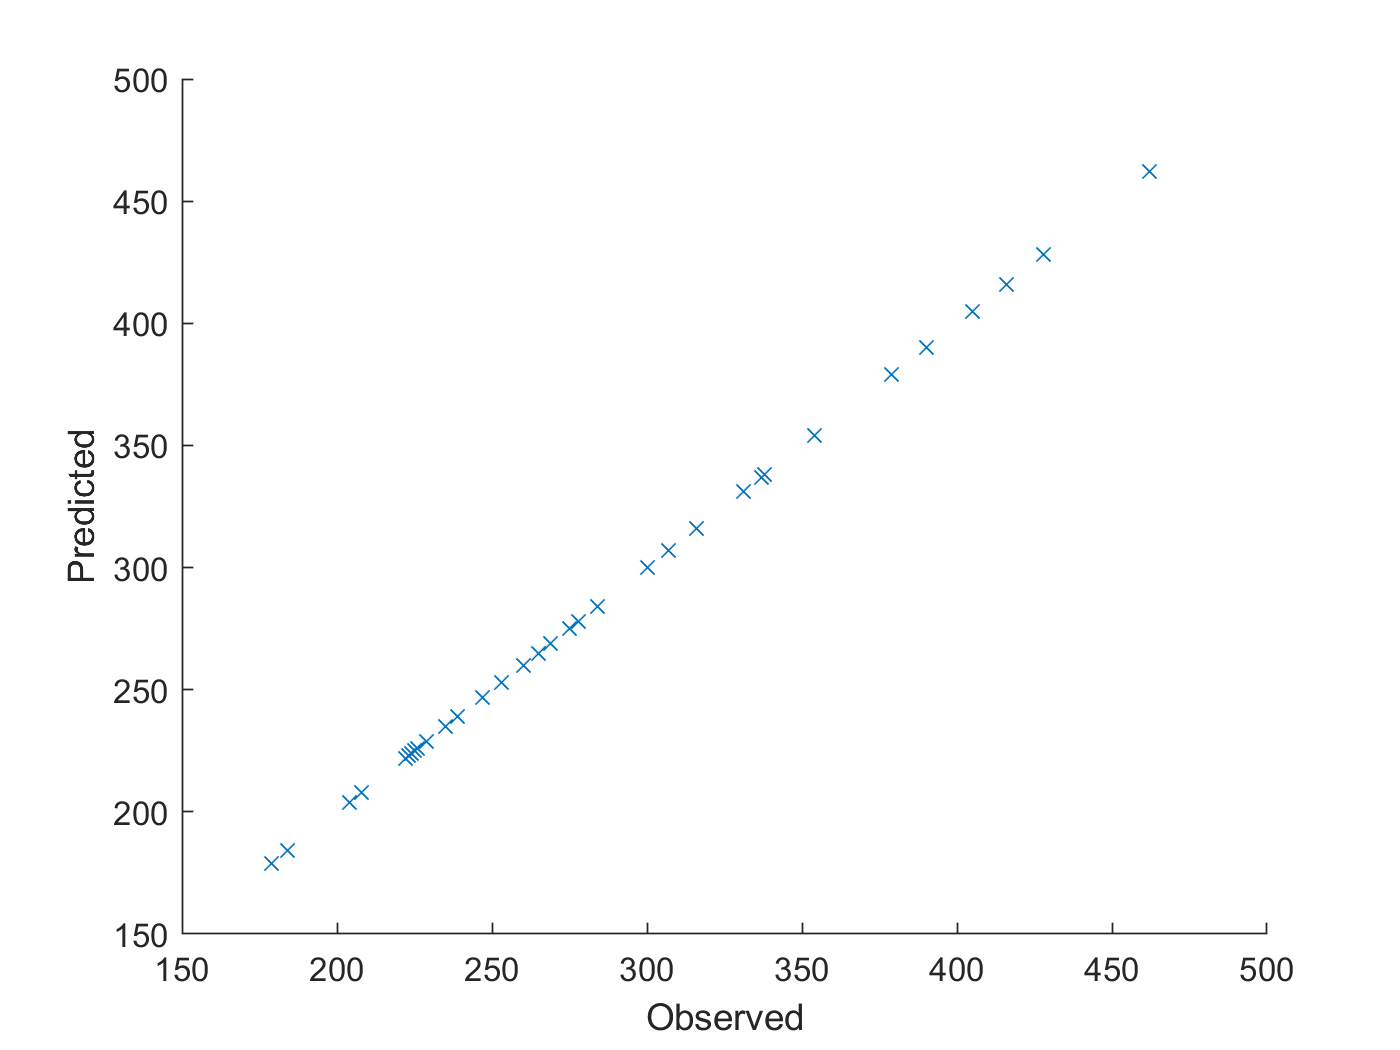

figure
hold on
plot(y,yhat,'x')
xlabel("Observed")
ylabel("Predicted")
hold off


(y - yhat)    % Errors

ans = 	1.0e+-9 *

   -0.5682
   -0.0883
   -0.0234
    0.1353
    0.0700
   -0.0985
    0.0377
   -0.0035
    0.2129
    0.0904


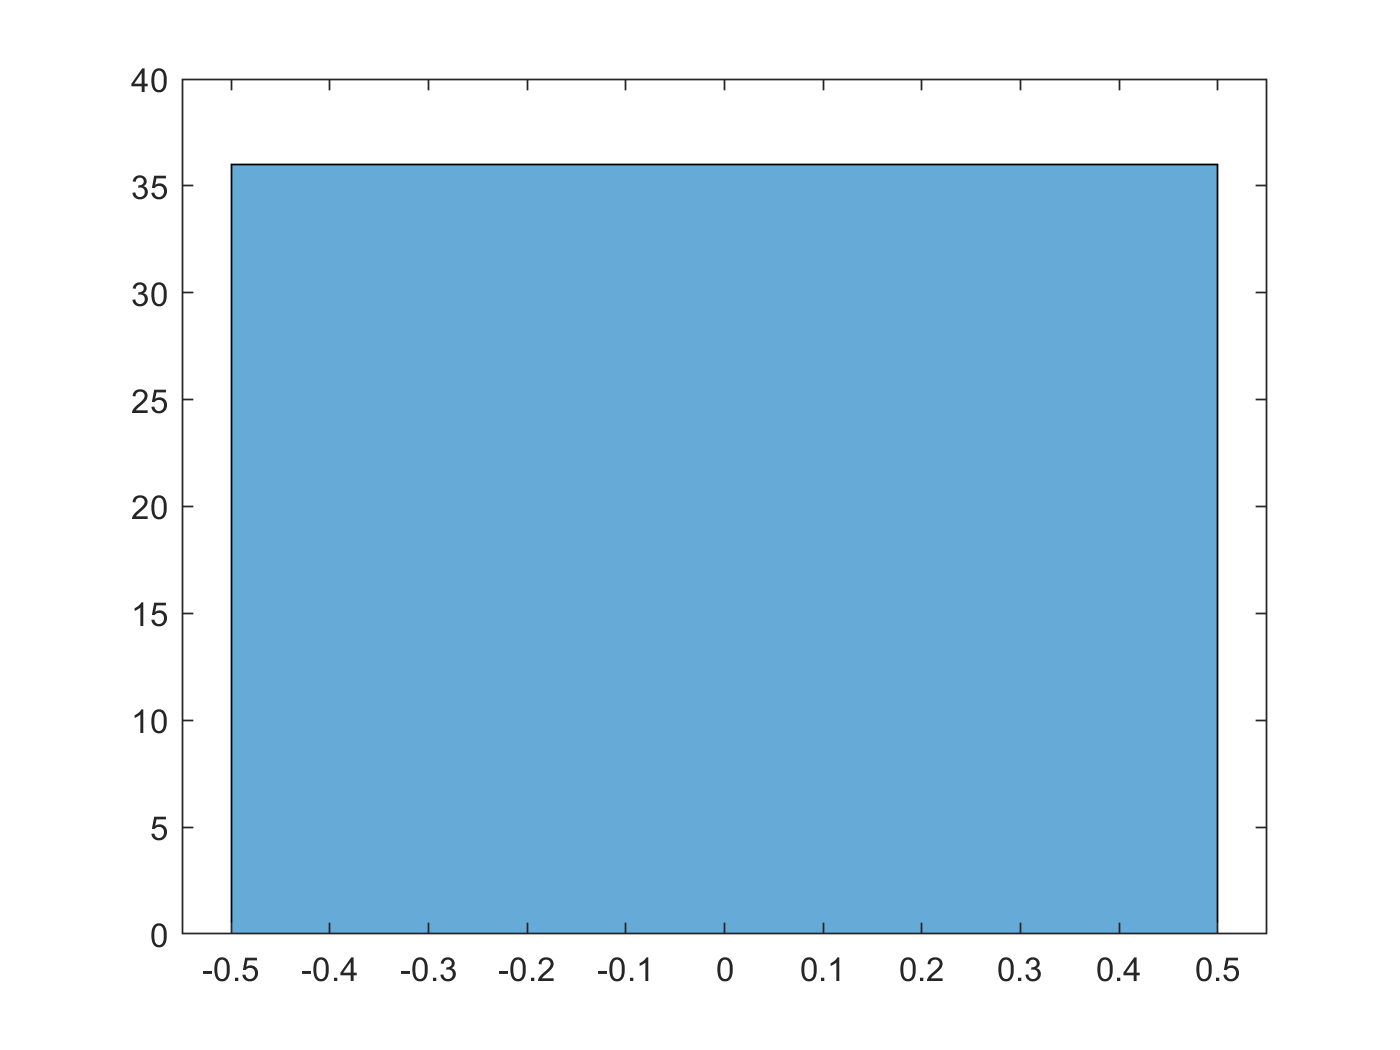

(y - yhat).^2 ;  % Squared Error
histogram((y - yhat).^2)

mean((y - yhat).^2);   % Mean Squared Error
RMSE = sqrt(mean((y - yhat).^2))  % Root Mean Squared Error

RMSE = 1.3307e-10

training set (b1,2)로 b2 예측 - 정확함.

% predict batch2 from model from model
idx = idx2;
Ic_ = [battery_dataset_new(idx).Ic];
x = (reshape(Ic_,input_size,[]))';
y = [battery_dataset_new(idx).cycle_life ]';

yhat = predict(mdl,x)

yhat =   212.0000
  109.0000
  184.0000
  237.0000
  267.0000
  204.0000
  398.0000
  348.0000
  251.0000
  311.0000


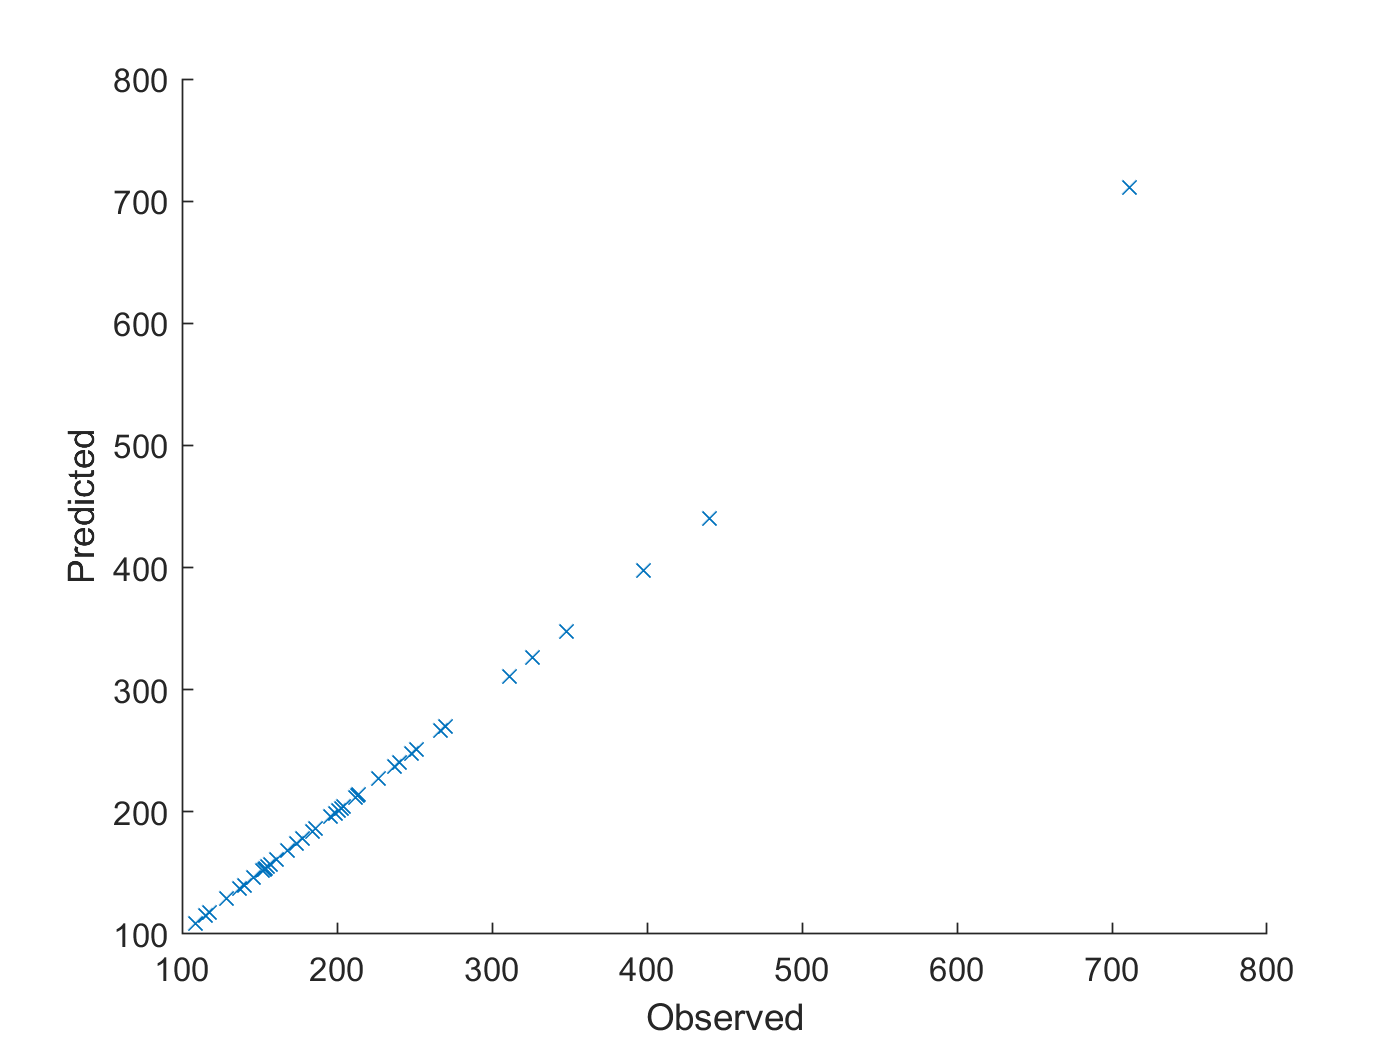

figure
hold on
plot(y,yhat,'x')
xlabel("Observed")
ylabel("Predicted")
hold off


(y - yhat)    % Errors

ans = 	1.0e+-9 *

    0.0863
    0.0430
    0.0534
    0.0914
   -0.0236
    0.0722
    0.1303
    0.0782
    0.0045
    0.0265


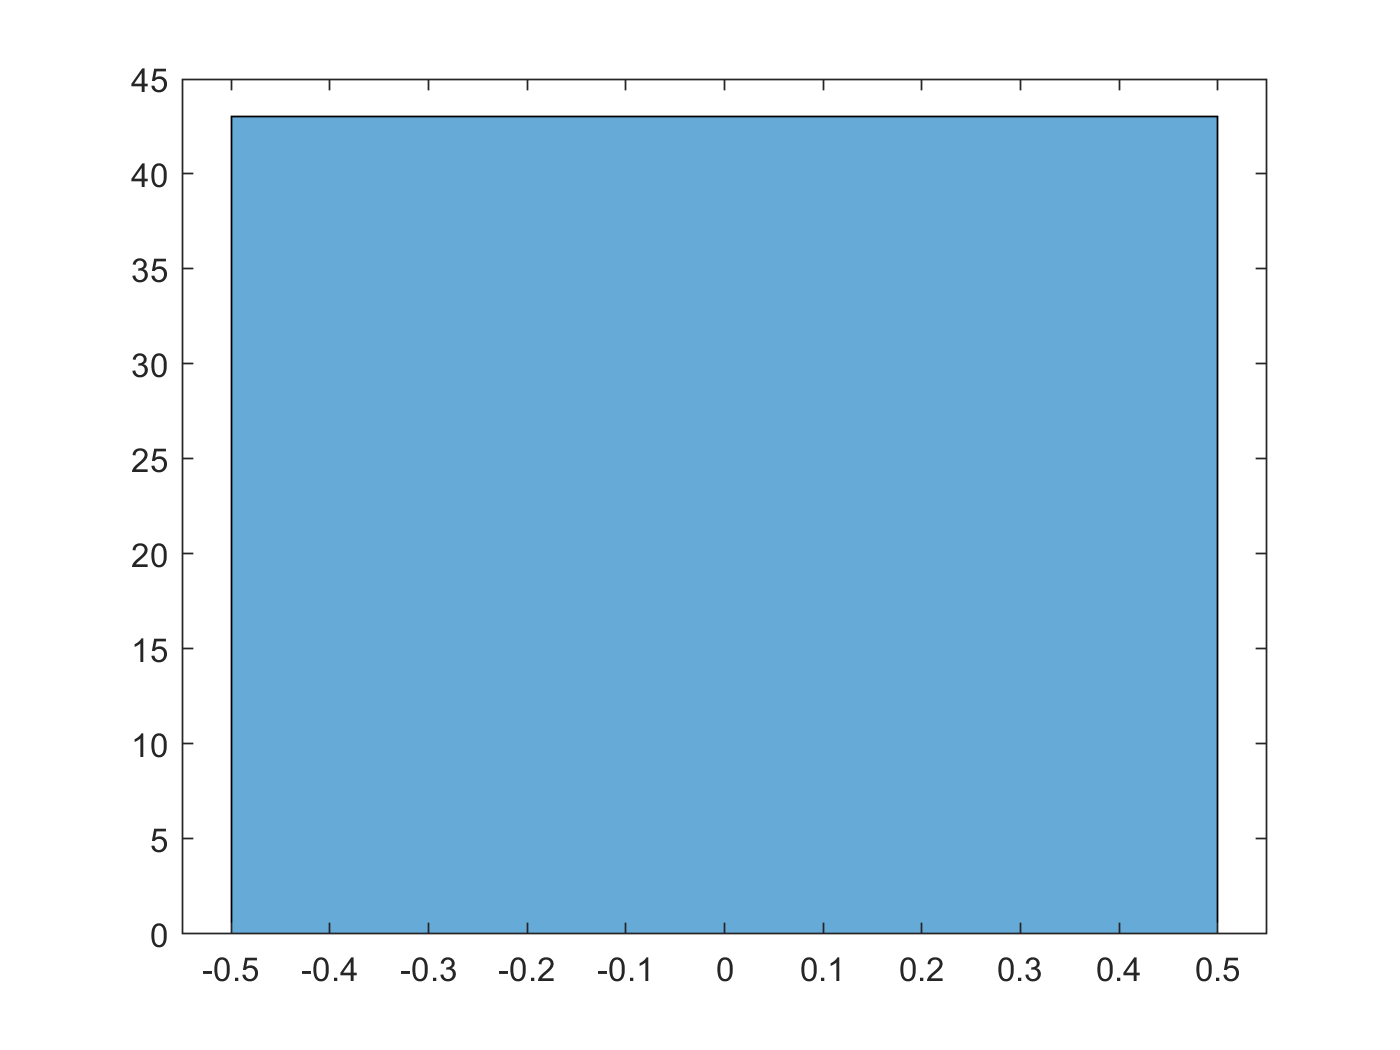

(y - yhat).^2 ;  % Squared Error
histogram((y - yhat).^2)

mean((y - yhat).^2);   % Mean Squared Error
RMSE = sqrt(mean((y - yhat).^2))  % Root Mean Squared Error

RMSE = 6.4283e-11

training set (b1,2)로 test set b3 예측 - RMSE가 매우 큼

% predict batch3 from model from model
idx = idx3;
Ic_ = [battery_dataset_new(idx).Ic];
x = (reshape(Ic_,input_size,[]))';
y = [battery_dataset_new(idx).cycle_life ]';

yhat = predict(mdl,x)

yhat = 	1.0e+04 *

   -1.7896
    0.6774
   -1.6366
   -3.7680
   -1.6148
    0.0788
    0.0515
   -1.3709
    0.6813
    0.0321


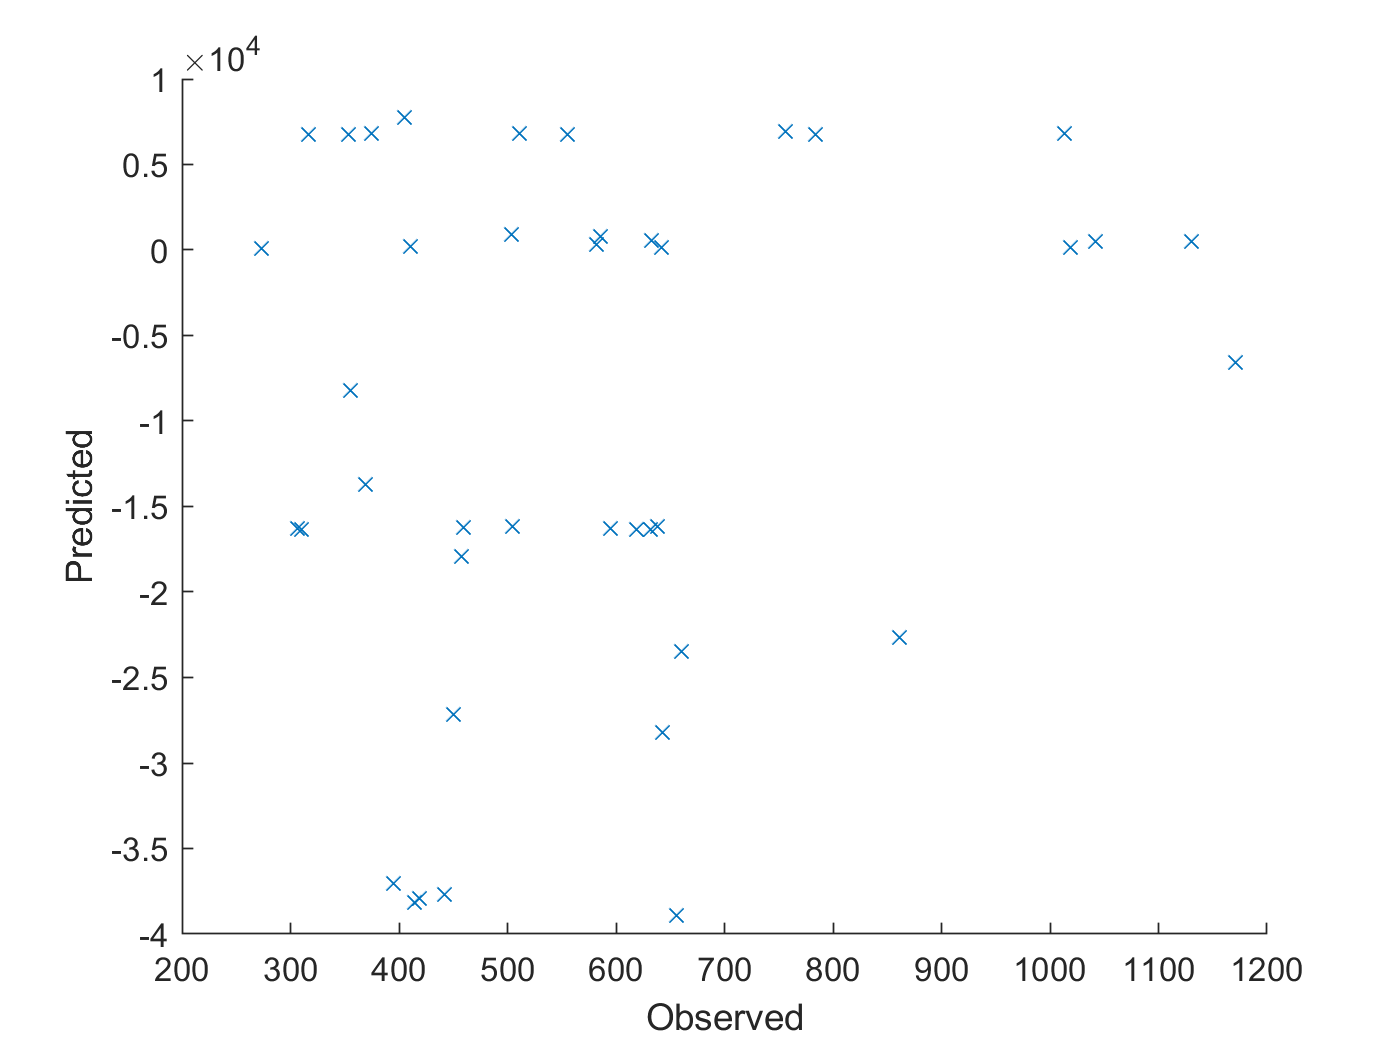

figure
hold on
plot(y,yhat,'x')
xlabel("Observed")
ylabel("Predicted")
hold off


(y - yhat)    % Errors

ans = 	1.0e+04 *

    1.8354
   -0.6219
    1.6998
    3.8122
    1.6786
   -0.0202
    0.0527
    1.4078
   -0.6438
    0.0261


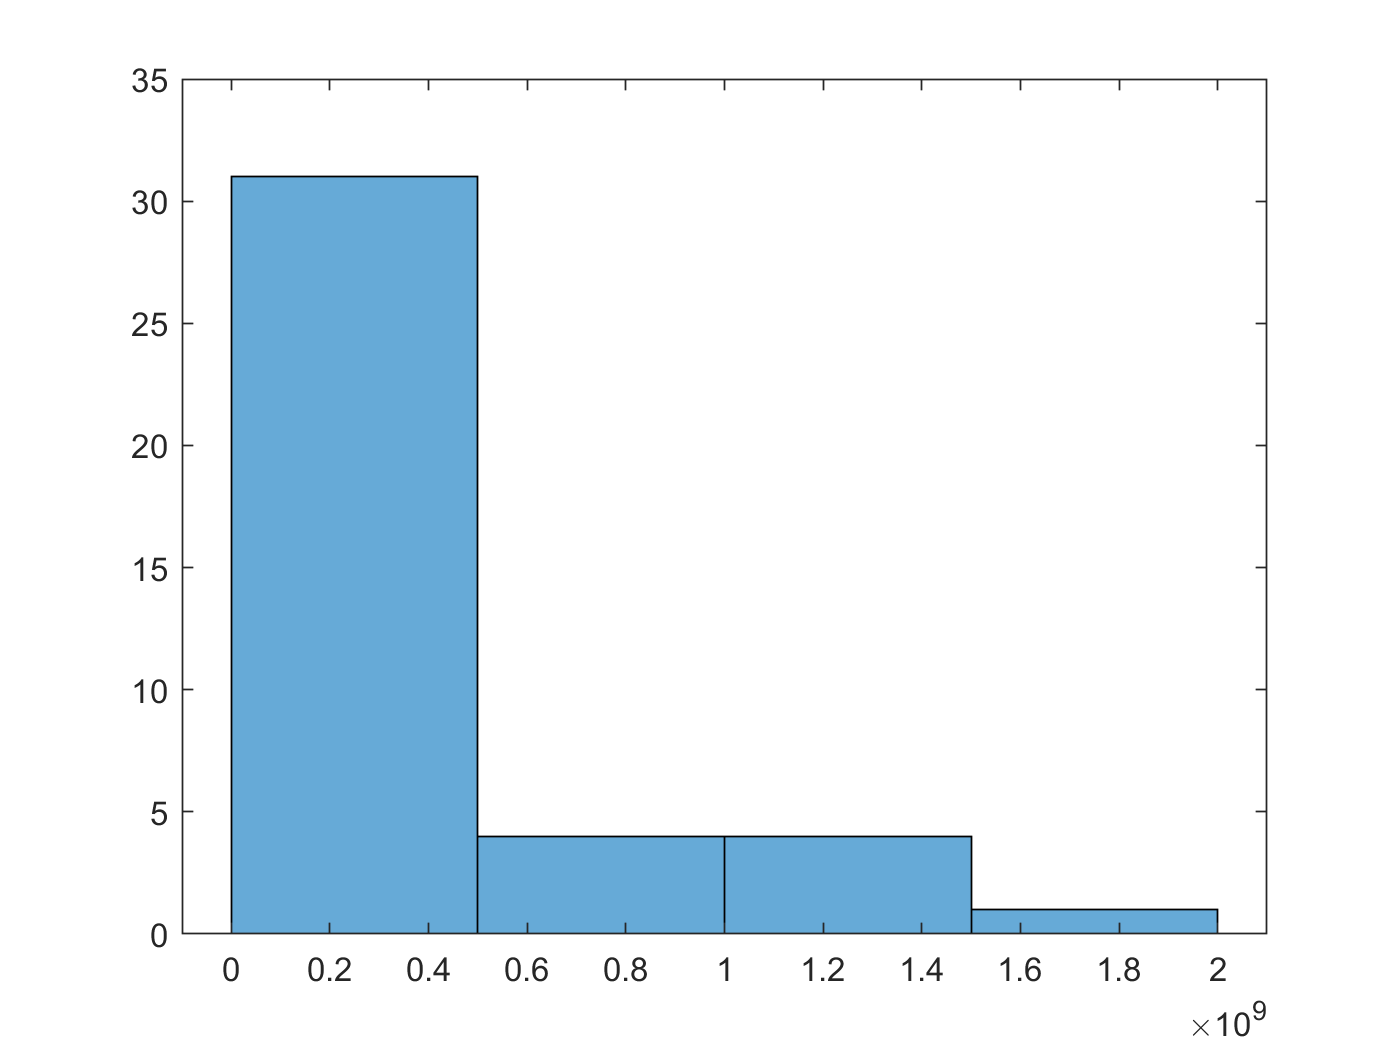

(y - yhat).^2;   % Squared Error
histogram((y - yhat).^2)

mean((y - yhat).^2);   % Mean Squared Error
RMSE = sqrt(mean((y - yhat).^2))  % Root Mean Squared Error

RMSE = 1.8297e+04

%%%%
% 선형회귀에서는 trainng set 에서는 잘 동작하나 test set인 batch3 에서는 오차가 크다.
